# Exercise 2

## Introduction

The objectives of this exercise are:

- Formulate an ***S***-matrix in MATLAB

- Rearrange an ***S***-matrix and note the effect

- Calculate the degrees of freedom and discuss its meaning

- Perform metabolic flux analysis (using a function, but you should know the equation)

- Critically interpret the results from MFA calculations 

**Report:** To help each other, you are encouraged to work in pairs on this exercise. This exercise is not graded and no report needs to be handed in. Meanwhile, the topics being discussed are exam material. **You are advised to work on this exercise *****after***** you have worked through the pre-study material for "Construct the S-matrix and flux analysis", and *****before***** the lecture on Exercise 2**, where help will be provided and the solutions to the exercise will be discussed. The solution to this exercise will also be made available on Canvas.

**Book contents:** This exercise covers chapters 2, 9 and 12 from the Systems Biology textbook: [https://doi.org/10.1017/CBO9781139854610](https://doi.org/10.1017/CBO9781139854610).

**Exercise files:** The current Live Script is accompanied by a `solveMFA.m` function file that is required for some of the questions. You can modify this script when answering the questions, also feel free to take down notes within this document. Via `Export -> Export to PDF...` in the menu bar you can then generate a file that you can also study outside of MATLAB.

% Check whether solveMFA is in the current working directory
pwd                  % This is the current working directory
isfile('solveMFA.m') % If ans = 0, then change working directory to location of solveMFA.m

**Background: **In this exercise we will construct an ***S***-matrix, perform metabolic flux analysis and have a look at rate equations. As an example, we will look at PHB production in yeast. In this paper the authors are looking to improve PHB production through diverting the flux and the effect of different carbon sources.

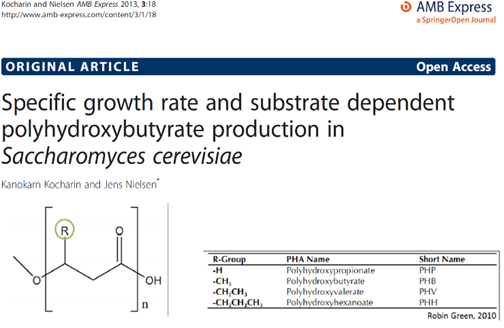

## Stoichiometric matrix

A simplified metabolic network is shown below, including glycolysis, PPP, TCA cycle and PHB production. Note that some reactions are lumped and simplified: AASyn represents amino-acid synthesis; NuclSyn represents nucleotide synthesis; ATPsyn represents ATP synthase. PPP, representing the transaldolase and transketolase reactions, has the reaction equation 2 Ribu5P + R5P → 2 Fru6P + GA3P.

Growth represents the polymerization of biomass precursors to form new biomass. ATPM is an ATP hydrolysis reaction that represents non-growth associated energy costs. Both of these will be discussed in more detail later in the course.

Because we apply the steady-state assumption, we can further simplify this network by lumping linear reactions and removing linear-dependent co-factors. Indicate which simplifications can be made on the network below, and then compare this to the reduced network that is shown further down this Live Script. Did you find all simplifications?

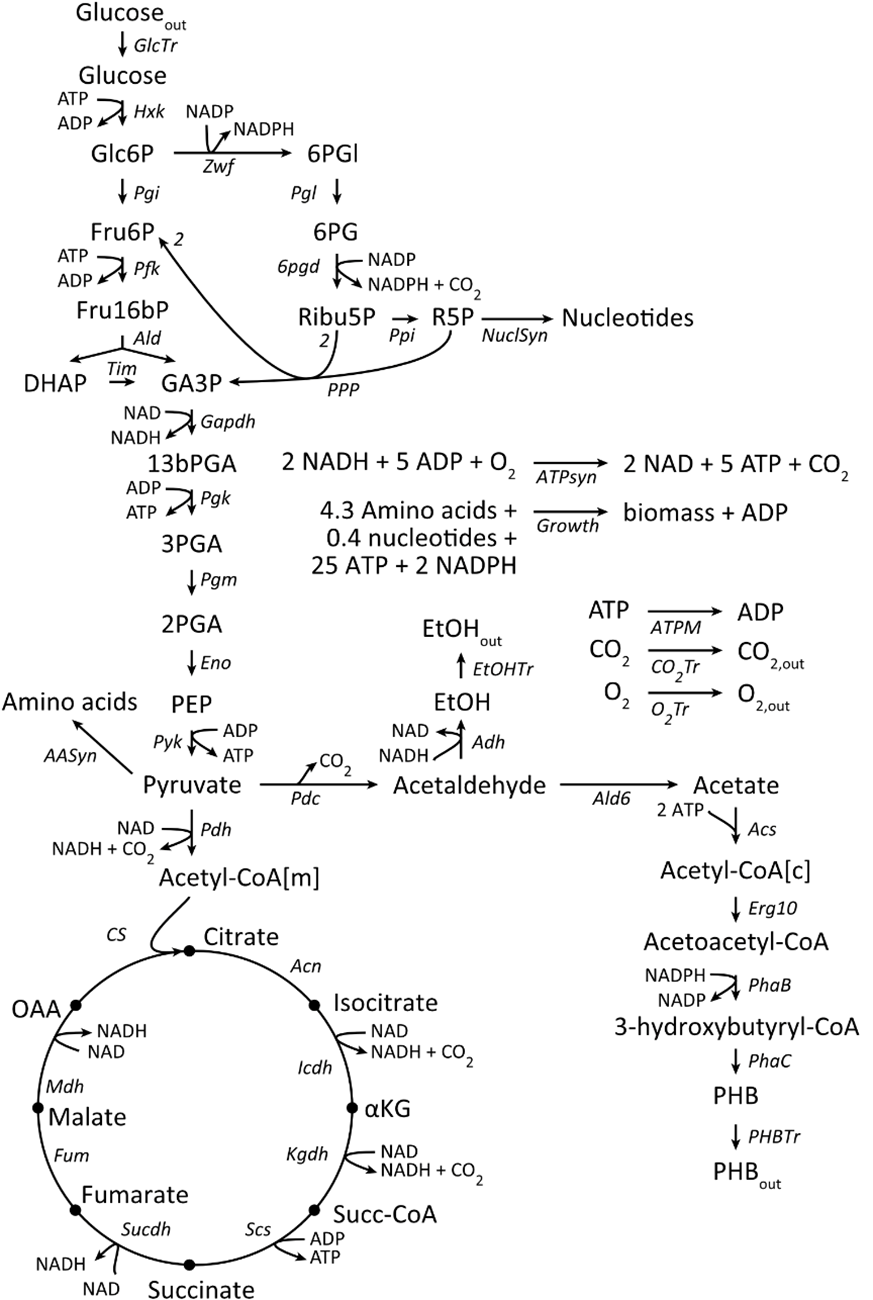

#### Q1: write down how to above network can be simplified:

- Reactions *GlcTr *and *Hxk *can be summed, so that new reaction (let's call it `v1)` is `Glucose_out + ATP -> Glc6P + ADP`.

- Production and consumption of ATP and ADP are linearily dependent, so `v1` can be further simplified to `Glucose_out + ATP -> Glc6P`, while `ATPsyn` can be simplified as `2 NADH + O2 -> 2 NAD + 5 ATP + CO2` (and can be simplified further?), and similar for other ATP involving reactions.

- ...

- ...

- (there are more than 5 ways...)

First try to find out the many ways this network can be simplified before looking at the reduced network!

**Reduced network:**

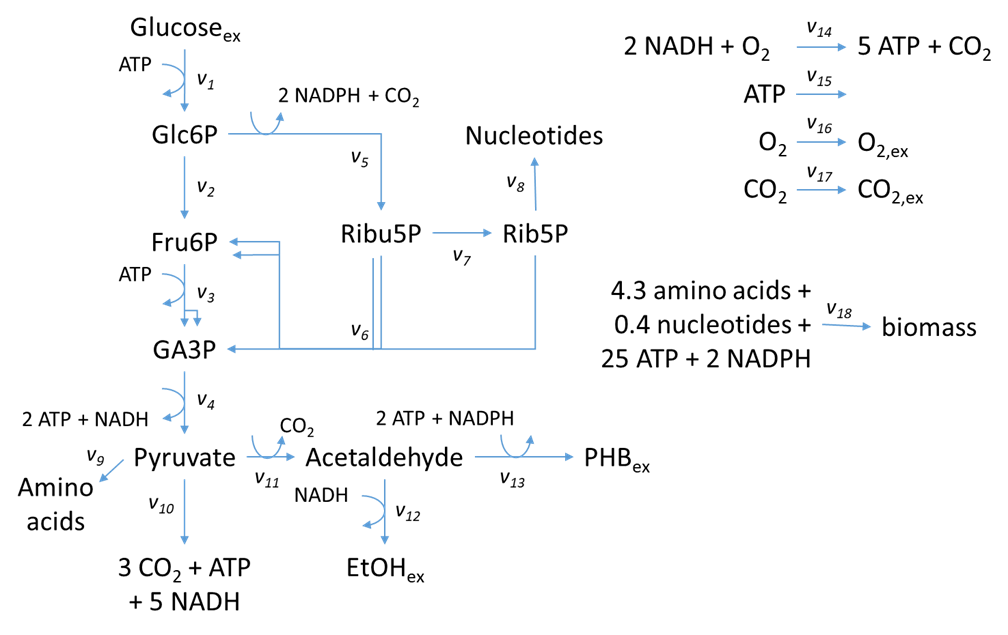

Below the **S**-matrix of the reduce network is shown, but one column and one row are not filled in yet (indicated with `X`).

**Q2**: Which reaction and metabolite are not yet filled in? You can assume that order of reactions is the same as in the figure: first *v1*, followed by *v2*, *v3* and so forth, with *v18* last. Answer: ...

**Q3**: Replace every `X` with the appropriate stoichiometric coefficient. Afterwards, run the section to generate the **S**-matrix in MATLAB.

S=[1,  -1,   X,   0,  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   1,   X,   0,   0,   2,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   X,  -1,   0,   1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   X,   1,   0,   0,   0,   0,  -1,  -1,  -1,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   X,   0,   1,  -2,  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   X,   0,   0,  -1,   1,  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   1,  -1,  -1,   0,   0,   0,   0,   0;
   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X,   X;
   0,   0,   X,   1,   0,   0,   0,   0,   0,   5,   0,  -1,   0,  -2,   0,   0,   0,   0;
   0,   0,   X,   0,   2,   0,   0,   0,   0,   0,   0,   0,  -1,   0,   0,   0,   0,  -2;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,  -1,   0,  -1,   0,   0;
   0,   0,   X,   0,   1,   0,   0,   0,   0,   3,   1,   0,   0,   1,   0,   0,  -1,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0,   0,   0,   0,  -4.3;
   0,   0,   X,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0,   0,   0,   0,   0,  -0.4;
  -1,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0;
   0,   0,   X,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1];

**Q4**: Is the **S**-matrix the **S_tot**, **S_in** or **S_ex** matrix? Answer: ...

**Q5**: How many degrees of freedom does the reduced network have, when does this make the model determined and how does this effect the calculation of fluxes? Answer: ...

**Q6**: From the reduced network, give two sets of reactions that would match the degrees of freedom and either  … 

- … not be sufficient to calculate all other fluxes. Answer: ...

- … be sufficient to calculate all other fluxes (this might be hard to see on paper, but we'll check this in MATLAB later). Answer: ...

## **Metabolic flux analysis**

**Q7**: Assume that we know the ethanol secretion (v12), O2 consumption (v16), CO2 excretion (v17) and growth rate (v18), with values 0, -5, 11 and 0.05, respectively. Perform metabolic flux analysis to find out the rate of PHB production in these conditions. Answer: ...

%% Perform MFA step by step
% Define S_in and S_ex
S_in  = S(1:14, :);  % Rows are specified first, then columns. Take row 1 to 14 (1:14) and all columns (:).
S_ex = S(15:end, :); % Take rows 15 until the last (15:end) and all columns (:).

% Define which fluxes are measured and which will be calculated
measFluxes = [12, 16, 17, 18];
calFluxes = [1:11, 13:15];

% Generate the S_in,meas and S_in,cal matrices
S_inmeas = S_in(:,measFluxes);
S_incal = S_in(:,calFluxes);

% Provide the measured flux values, and determine the unknown fluxes
vmeas = [0; -5; 11; 0.05];
vcal = (- S_incal^-1) * (S_inmeas * vmeas);
% Print the fluxes of calculated fluxes
vcal

% Rearrange the fluxes
allFluxes(measFluxes) = vmeas;
allFluxes(calFluxes) = vcal;
% Give the n-th flux (here, n=13, giving us the rate of v13):
v13 = allFluxes(13)

To simplify the code above, we have prepared a function called `solveMFA`, where you can give the following input: S_in matrix, the index numbers of those fluxes that are measured and the values of those measurements. The function performs the MFA, similarly as above, and rearranges the fluxes to get an ordered list of total fluxes.

solveMFA(S_in, [12, 16, 17, 18], [0, -5, 11, 0.05]);

**Q8**: From your above calculation, what is the yield of PHB on glucose? Answer: ...

The **S**-matrix is defined in a certain order, where the columns and rows correspond to specific reactions and metabolites. However, this order does not have any meaning, we can move columns and rows around while the **S**-matrix still represents the same network and the calculated solutions are still the same.

**Q9**: Confirm whether you still get the same PHB production rate by solving question **Q7** with the rearranged **S**-matrix. How did you rearrange the **S**-matrix and did it give the same solution? Answer: ....

% Make a new S matrix, where some of the metabolites have changed position.
% This can be done by defining the new order, for instance [2:end, 1],
% where the first entry is now placed last. Do such an arrangement of the
% metabolites in the S-matrix.

% Here is an example, but you can make any changes to the order of columns
% and rows.

Snew = S([1,3,4,2,5:end], [2:end, 1]);
% Here the first four rows are shuffled, and the first column is placed
% last. You can test whether this S-matrix still give the same solution by
% trying to solve question Q7 (see code above) again with this new S-matrix
% and compare the result.

solveMFA( );

To prevent confusion we will return to using the same **S**-matrix as in **Q7** for all the remaining questions.

**Q10**: In **Q6** you proposed two sets of known reaction rates that either would or would not allow calculation of all fluxes. Check whether your predictions were correct. Answer: ...

% Run solveMFA with the two different sets of measured reaction fluxes.
% Remember the input for solveMFA.
% Does it matter what flux values you specify for the measured fluxes?

solveMFA( );
solveMFA( );

We want to determine what is the ATP maintenance requirements of the wild-type strain (so there is no PHB production). To do this, we run a continuous cultivation of the yeast in a bioreactor with a culture volume of 500 mL, constant aeration with oxygen and a constant growth rate of 0.05 /h. The constant growth rate is obtained because there is a constant inflow of fresh medium into the cultivation (and an equal outflow) with the same rate of 0.05 /h, which means that over 20 hours the culture volume has been replaced with new culture medium. As a result, the cells will grow at the same rate as new growth medium is supplied. The glucose concentration in the feed medium is 27 mM, and the amount of cells in the bioreactor, or the biomass concentration, is 2 g dry cell weight (DCW) per liter. From this, you can calculate that the specific glucose uptake rate is 0.675 mmol / gDCW / h.

**Q11**: As a bonus question, can you show how this is calculated? [You don't need to be able to answer this question to complete the rest of the exercise]

% Here you can calculate the glucose uptake rate based on the information
% provided above.


From this cultivation we have also measured the amount of carbon dioxide that is secreted by the cells by measuring the amount coming from the bioreactor, and we have calculated a rate of 3 mmol / gDCW / h.

**Q12**: Combine this information with what was already described for **Q11 **and calculate the ATP maintenance requirement of the wild-type strain. Answer: ...

% Which fluxes are known? Which reactions are those? Use solveMFA to
% determine the unknown fluxes. Which flux indicates ATP maintenance
% requirement?

solveMFA( );

We also ran an anaerobic cultivation with the same strain, at the same dilution rate, volume and glucose concentration in the feed medium.

**Q13: **Compared to the conditions described for **Q11**, do you think the amount of cells in the bioreactor (can also be described as biomass concentration) will be higher, lower, or unchanged in comparison with the earlier aerobic cultivation? You don't need to do any calculation to answer this, just think about what role oxygen has in aerobic metabolism and what effect the absence of oxygen would have. Answer: ...

**Q14**: We measure and calculate a glucose uptake rate of 3.75 mmol/gDCW/h, now determine what the ATP maintenance is in these conditions. Answer: ...

% Similar as above, which fluxes are known? Use solveMFA.

solveMFA( );

Now we move on to the engineered strain. Looking at the metabolic network, you can imagine that the PHB production will be highest when there is no growth and no ethanol secretion, this way you are not wasting any carbons! Before doing some experiments, let's first see what the model can tell us about PHB production.

**Q15**: Assume that ATP maintenance is as you calculated in **Q12**, what are the PHB production rates if the glucose uptake is either (a) 1 mmol/gDCW/h or (b) 5 mmol/gDCW/h? Answer: ...

% Similar as above, which fluxes are known? Use solveMFA.

solveMFA( );
solveMFA( );

**Q16**: Considering your answer from the previous question, when the glucose uptake increase five-fold, by how much did the PHB production rate increase? Can you explain this? Answer: ...

**Q17**: Have another good look at the reaction rates that you calculated in **Q15**. Can you spot a problem with some of the reaction fluxes? Answer: ...

Now we have actually done an aerobic cultivation with the engineered strain, and we have measured and calculated some rates. The glucose uptake was 4 mmol / gDCW / h, the growth rate 0.3 and no ethanol was secreted.

**Q18**: What is the rate of PHB production? Answer: ...

% Similar as above, which fluxes are known? Use solveMFA.

solveMFA( );

**Q19**: What was the yield of PHB on glucose? What is the yield if the molecular weight or the number of carbon atoms is taken into account? Answer: ...